% sep2021
% fft operation without using inbuilt function
% only capable to compute fft upto N = 128 but it can be easily expendable
clc
clear
% generating signal
T12 = 2; N12 = 512; Ts12 = T12/N12;
t12 = Ts12*(0:(N12-1));
phi1 = pi/3; phi2 = pi/2;
x = cos(5*pi*t12-phi1) + 3*cos(8*pi*t12-phi2);
% length of the signal
N = length(x);
% number of stage required
M = log2(N);
% adding zeros 
if (rem(M,1) ~= 0)
    re =rem(M,1);
    M=M-re+1;
    Ne = 2^M;
    x = [x,zeros(1,Ne-N)];
else
    Ne = N;
end
% calc. using inbuild function
x_fft =fft(x);
% bitreversing
x = bitrevorder(x);
% instialization of variables used for different stages
temp = zeros(1,Ne);
temp2 = zeros(1,Ne);
temp3 = zeros(1,Ne);
temp4 = zeros(1,Ne);
temp5 = zeros(1,Ne);
temp6 = zeros(1,Ne);
temp7 = zeros(1,Ne);
% code 
for l = 1:M
    if l==1
        for t=0:2:Ne-1
            temp(t+1:t+2) = temp(t+1:t+2) + myfun(x(t+1:t+2),2^l);
        end
        out = temp;
    end
    if l==2
        for k=0:4:Ne-1
            temp2(k+1:k+4) = temp2(k+1:k+4) + myfun(temp(k+1:k+4),2^l);
        end  
        out= temp2;
    end
    if l==3
        for k=0:8:Ne-1
            temp3(k+1:k+8) = temp3(k+1:k+8) + myfun(temp2(k+1:k+8),2^l);
        end  
        out= temp3;
    end
    if l==4
        for k=0:16:Ne-1
            temp4(k+1:k+16) = temp4(k+1:k+16) + myfun(temp3(k+1:k+16),2^l);
        end  
        out= temp4;
    end
    if l==5
        for k=0:32:Ne-1
            temp5(k+1:k+32) = temp5(k+1:k+32) + myfun(temp4(k+1:k+32),2^l);
        end  
        out= temp5;
    end
    if l==6
        for k=0:64:Ne-1
            temp6(k+1:k+64) = temp6(k+1:k+64) + myfun(temp5(k+1:k+64),2^l);
        end  
        out= temp6;
    end
    if l==7
        for k=0:128:Ne-1
            temp7(k+1:k+128) = temp7(k+1:k+128) + myfun(temp6(k+1:k+128),2^l);
        end  
        out= temp7;
    end
end
x % values of x 

x =     0.5000   -0.5000    0.8660   -0.8660   -0.9659    0.9659   -0.2588    0.2588    0.6088   -0.6088   -0.7934    0.7934    0.1305   -0.1305    0.9914   -0.9914    3.9979    2.0021    3.0654    2.9346    2.2482    3.7518    3.6593    2.3407   -3.3214   -2.6786   -3.9469   -2.0531   -2.1031   -3.8969   -2.5577   -3.4423    2.9705    1.2721    2.6494    1.5933    1.1474    3.0952    2.3484    1.8942   -1.9584   -2.2842   -3.1080   -1.1347   -1.5388   -2.7038   -1.3085   -2.9342    3.0322    1.2105


x_fft % fft calc. using inbuild function

x_fft = 1.0e+02 *

   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   1.2800 - 2.2170i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 7.6800i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i


out   % fft calc. using myfunction (DIT)

out = 1.0e+02 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.3200 - 0.5543i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 1.9200i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i


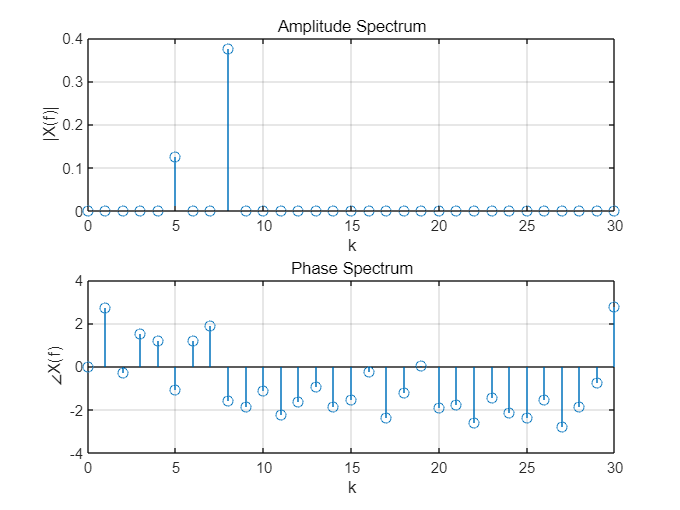

figure()
X_amp = abs(out)/N;
X_phase = angle(x_fft);
k = 0:30;
subplot(211);
stem(k,X_amp(1:length(k)));
grid;
xlabel('k');
ylabel('|X(f)|');
title('Amplitude Spectrum');
subplot(212);
stem(k,X_phase(1:length(k)));
grid;
xlabel('k');
ylabel('\angleX(f)');
title('Phase Spectrum');

function out = myfun(inp,N)
    twi = twiddle(N);
    inp1 = [inp(1:N/2),inp(1:N/2)];
    inp2 = [inp(N/2+1:N),inp(N/2+1:N)];
    out = zeros(1,N);
    for i=1:N
        out(i) = inp1(i) + twi(i)*inp2(i);
    end
end

function out = twiddle(N)
out = zeros(1,N);
for k=1:N
  out(k) = exp(-1j*2*pi*(k-1)/N);
end
end



% author: Robin Singh Som

